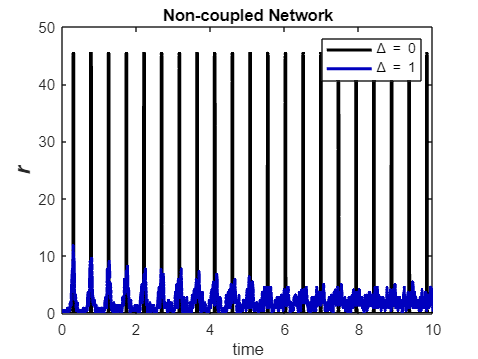

load('S_matlabresincro.mat');
load('V_matlabsincro.mat');
load('S_matlabnoresincro.mat');
load('V_matlabnosincro.mat');


tvec = 0.001:0.001:10;

%S_matlab = movmean(S_matlab,80);
%V_matlab = movmean(V_matlab,80);


figure;
plot(tvec,S_matlab,'color','black','LineWidth',2)
hold on
plot(tvec,S_matlabnosinc,'color',[0, 0, 190] / 255,'LineWidth',2)
title('Non-coupled Network')
xlabel('time')
ylabel('r','FontSize',15, 'FontAngle', 'italic','FontWeight', 'bold')
% Add legend
legend('\Delta = 0', '\Delta = 1');

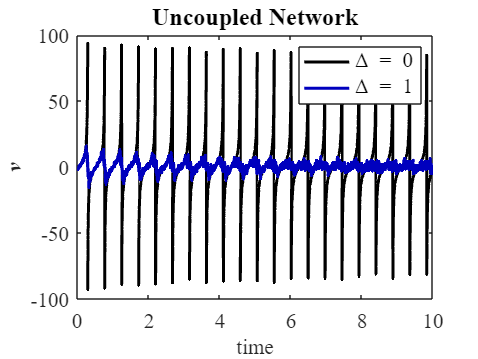


figure;
plot(tvec,V_matlab,'color','black','LineWidth',2)
hold on
plot(tvec,V_matlabnosinc,'color',[0, 0, 190] / 255,'LineWidth',2)
title('Uncoupled Network')
xlabel('time')
ylabel('v','FontSize',15, 'FontAngle', 'italic','FontWeight', 'bold')
% Add legend
legend('\Delta = 0', '\Delta = 1');

% Set font to Times New Roman and increase font size
set(gca, 'FontName', 'Times New Roman', 'FontSize', 14);
set(get(gca,'XLabel'), 'FontName', 'Times New Roman', 'FontSize', 14);
set(get(gca,'YLabel'), 'FontName', 'Times New Roman', 'FontSize', 14);
set(get(gca,'Title'), 'FontName', 'Times New Roman', 'FontSize', 16);
set(get(gca,'Legend'), 'FontName', 'Times New Roman', 'FontSize', 14);